# **Engineering Fluid Mechanics **

# **Term Project 1**

## **Pipe Structre Calculater 1**

2024/11/07 Uiseong An

**Problem 1**

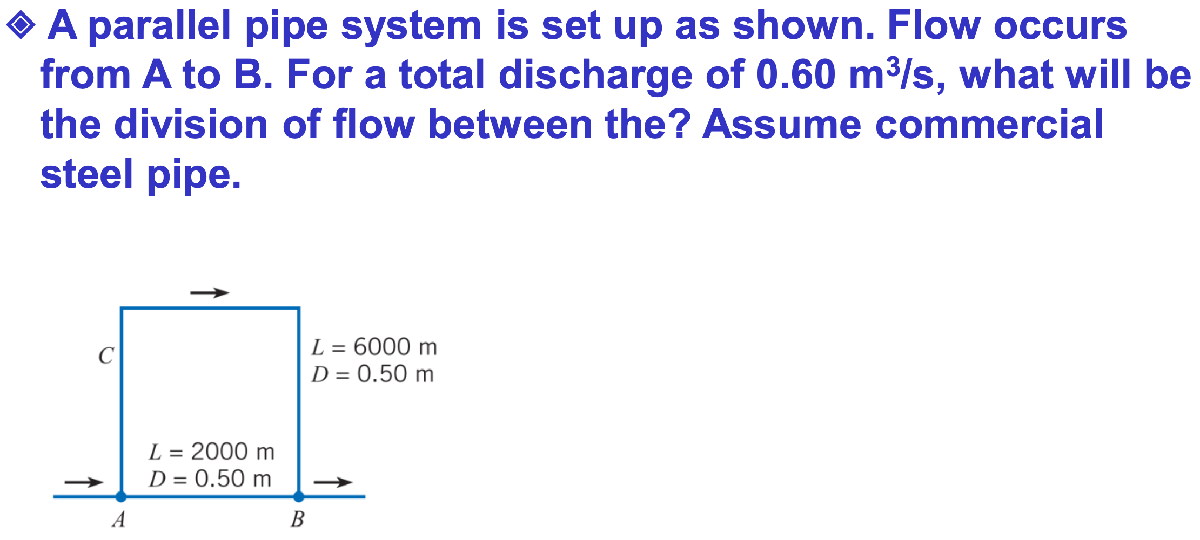

#### set value

�Basic information

g = 9.81;
ccw = -1; %Counter clock wise

Pipe information

L1 = 6000;
D1 = 0.5;
L2 = 2000;
D2 = 0.5;

Commercial Steel Pipe

ks = 0.046 * 10^-3; %m

Total Discharge $Q=0\ldotp 60\;m^3 /s\;$

Q = 0.6;

Guess Q

Q1 = 0.3;
Q2 = ccw * (Q - Q1);

Temperature : 20 degrees Water

nu = 1 * 10^-6;

#### Basic Calculation

A1 = pi * D1^2 / 4;
A2 = pi * D2^2 / 4;

#### Find the correct anser to the roop

for i = 1:200
    V1 = abs(Q1 / A1); %abs()-> if V is (-)
    V2 = abs(Q2 / A2); %Re is the wrong anser

    Re1 = V1 * D1 / nu;
    Re2 = V2 * D2 / nu;

    %Colebrook-White Formula
    f1 = 0.25 / (log10((ks/3.7/D1) + (5.74/(Re1^0.9))))^2;
    f2 = 0.25 / (log10((ks/3.7/D2) + (5.74/(Re2^0.9))))^2;

    %Darcy-Eeisbach Equation
    hf1 = f1 * L1 * V1^2 / D1 / 2 / g;
    hf2 = ccw * f2 * L2 * V2^2 / D2 / 2 / g; % ccw -> Opposite direction
    
    %Total head loss
    hf = hf1 + hf2;

    hf_Q = hf1/Q1 + hf2/Q2;

    x = 2; %Usely 2 in Darcy-Weisbach eq
    delta = -hf / hf_Q / x;

    Q1 = Q1 + delta;
    Q2 = Q2 + delta;

    if abs(delta) < 10^-3
        disp(['Re1 =  ', num2str(Re1, '%.4e')]);
        disp(['Re2 =  ', num2str(Re2, '%.4e')]);
        disp(['Delta =  ', num2str(delta, '%.4e')]);
        disp(['Q1 =  ', num2str(Q1, '%.4e')]);
        disp(['Q2 =  ', num2str(Q2, '%.4e')]);
        Q1 - Q2
        break;
    end
end

Re1 =  5.5040e+05


Re2 =  9.7749e+05


Delta =  -5.3514e-04


Q1 =  2.1560e-01


Q2 =  -3.8440e-01


ans = 0.6000